# 034IN -FONDAMENTI DI AUTOMATICA - FUNDAMENTALS OF AUTOMATIC CONTROL 

# Second Partial Examination -  A.Y. 2024/2025

**June 6, 2025**

# Design of a Strictly Proper Controller for a Plant with a Parameter Affected by  Interval Uncertainty

## Description of the Feedback Control System

Consider the feedback control system described by the block-scheme shown in the following figure

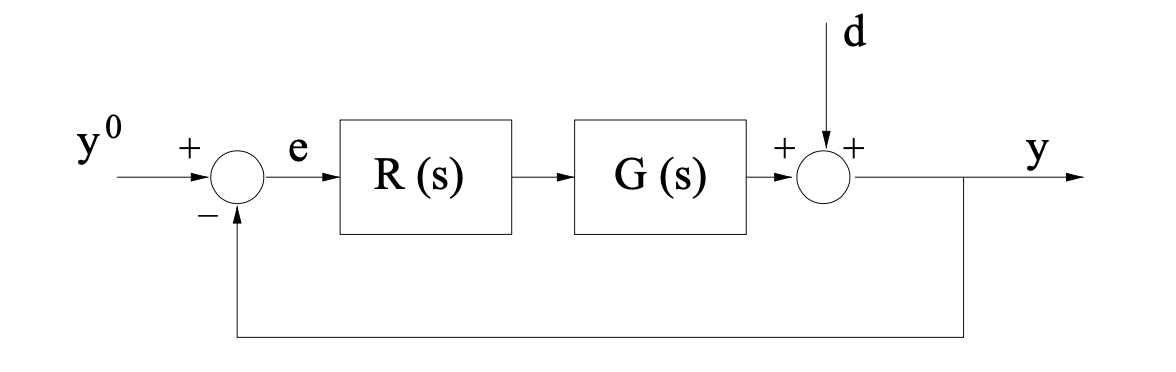	

where $G(s)$ is given by                


$$G(s) = 9\,\frac{\left(1+\frac{s}{10} \right)}{\left(1+\tau\,s \right)\,\left(1+\frac{s}{256} \right)}\;,\qquad \tau \in \left[\frac{1}{2}\,,\; 10 \right]\;\text{sec}$$


**Note**: This means that the system has a striclty proper transfer function with two distinct, real poles, and only one zero. One of the poles is exactly known, whereas the second one is partially unknown. The time constant $\tau$ of this pole takes on a value contained within the assigned range $\big[0.5\,,\; 10\big]\; \text{sec}$. 

## **Question**		

**Q1**: Design a **strictly** **proper** **controller** $C(s)$ such that all following requirements are simultaneously met: 

- Zero steady-state error in unit step response (closed-loop) $e(\infty) =0$, against disturbances given by 


$$\left\{ \begin{array}{rcl}
y^o(t) &=& 1(t) \\
d(t) &=& A\cdot 1(t)\,,\; A \in \mathbb{R}
\end{array} \right. \quad \Longrightarrow \quad e_{\infty} = 0
$$


            where $\mathbf{1}(t)$ denotes the unit step function;

- phase margin greater than or equal to $40^\circ$: $\varphi_m \ge 40^{\circ}$;

- settling time [at $1\%$ as usual] in the (closed-loop) unit step output less than or equal to $10$ seconds: $t_{s\,1\%} \le 10$ sec

### Hint

How to handle the unknown time constant $\tau$? A good practice is to identify the **worst-case scenario** and design the controller $C(s)$ according to that scenario.

## Solution

Initialisation code (clearing the MATLAB workspace, adding the path of the BodeDiagram subfolder to the MATLAB search-path)

clear variables

% adding folders (and subfolders) to search path
addpath(genpath('BodeDiagram/'))

% let's define the transfer function builder element
s=tf('s');


### Preliminary Analysis


$$G(s) = 9\,\frac{\left(1+\frac{s}{10} \right)}{\left(1+\tau\,s \right)\,\left(1+\frac{s}{256} \right)}\;,\qquad \tau \in \left[\frac{1}{2}\,,\; 10 \right]\;\text{sec}$$


According to (Q1.1), the regulator must have a pole at $s=0$: $\quad C_1(s) = \frac{\mu_C}{s}\;,\quad \mu_C >0$

tauMIN = 0.5; tauMAX = 10;
tauR = 4.5;

% static regulator, according to (Q1,1)
muC = 1;
C1s = muC/s;

% what is the worst-case scenario?
Gs1 = 9*(1+s/10)/(1+tauMIN*s)/(1+s/256);
Gs2 = 9*(1+s/10)/(1+tauMAX*s)/(1+s/256);
Gs3 = 9*(1+s/10)/(1+tauR*s)/(1+s/256);

Ls1 = C1s*Gs1;
Ls2 = C1s*Gs2;
Ls3 = C1s*Gs3;

Let's analyse the (Q1.3) requirement:


$$t_{s\,1\%} \le 10 \quad \Longleftrightarrow \quad 
\left\{ \begin{array}{rclcrclcrcl}
\varphi_m &>& 75^{\circ} &\Longrightarrow & t_{s\,1\%}&=&\frac{4.6}{\omega_c} \le 10 &\Longrightarrow & \omega_c &\ge &\frac{46}{100} \\ \\
\varphi_m &<& 75^{\circ} &\Longrightarrow &  t_{s\,1\%}&=&\frac{4.6}{\xi\,\omega_n} \approx \displaystyle \frac{4.6}{\frac{\varphi_m}{100}\,\omega_c} \le 10 &\Longrightarrow & \varphi_m\cdot \omega_c &\ge& 46
\end{array} \right. \qquad (*)$$


Consider the first scenario ( $\varphi_m > 75^{\circ}$ ):

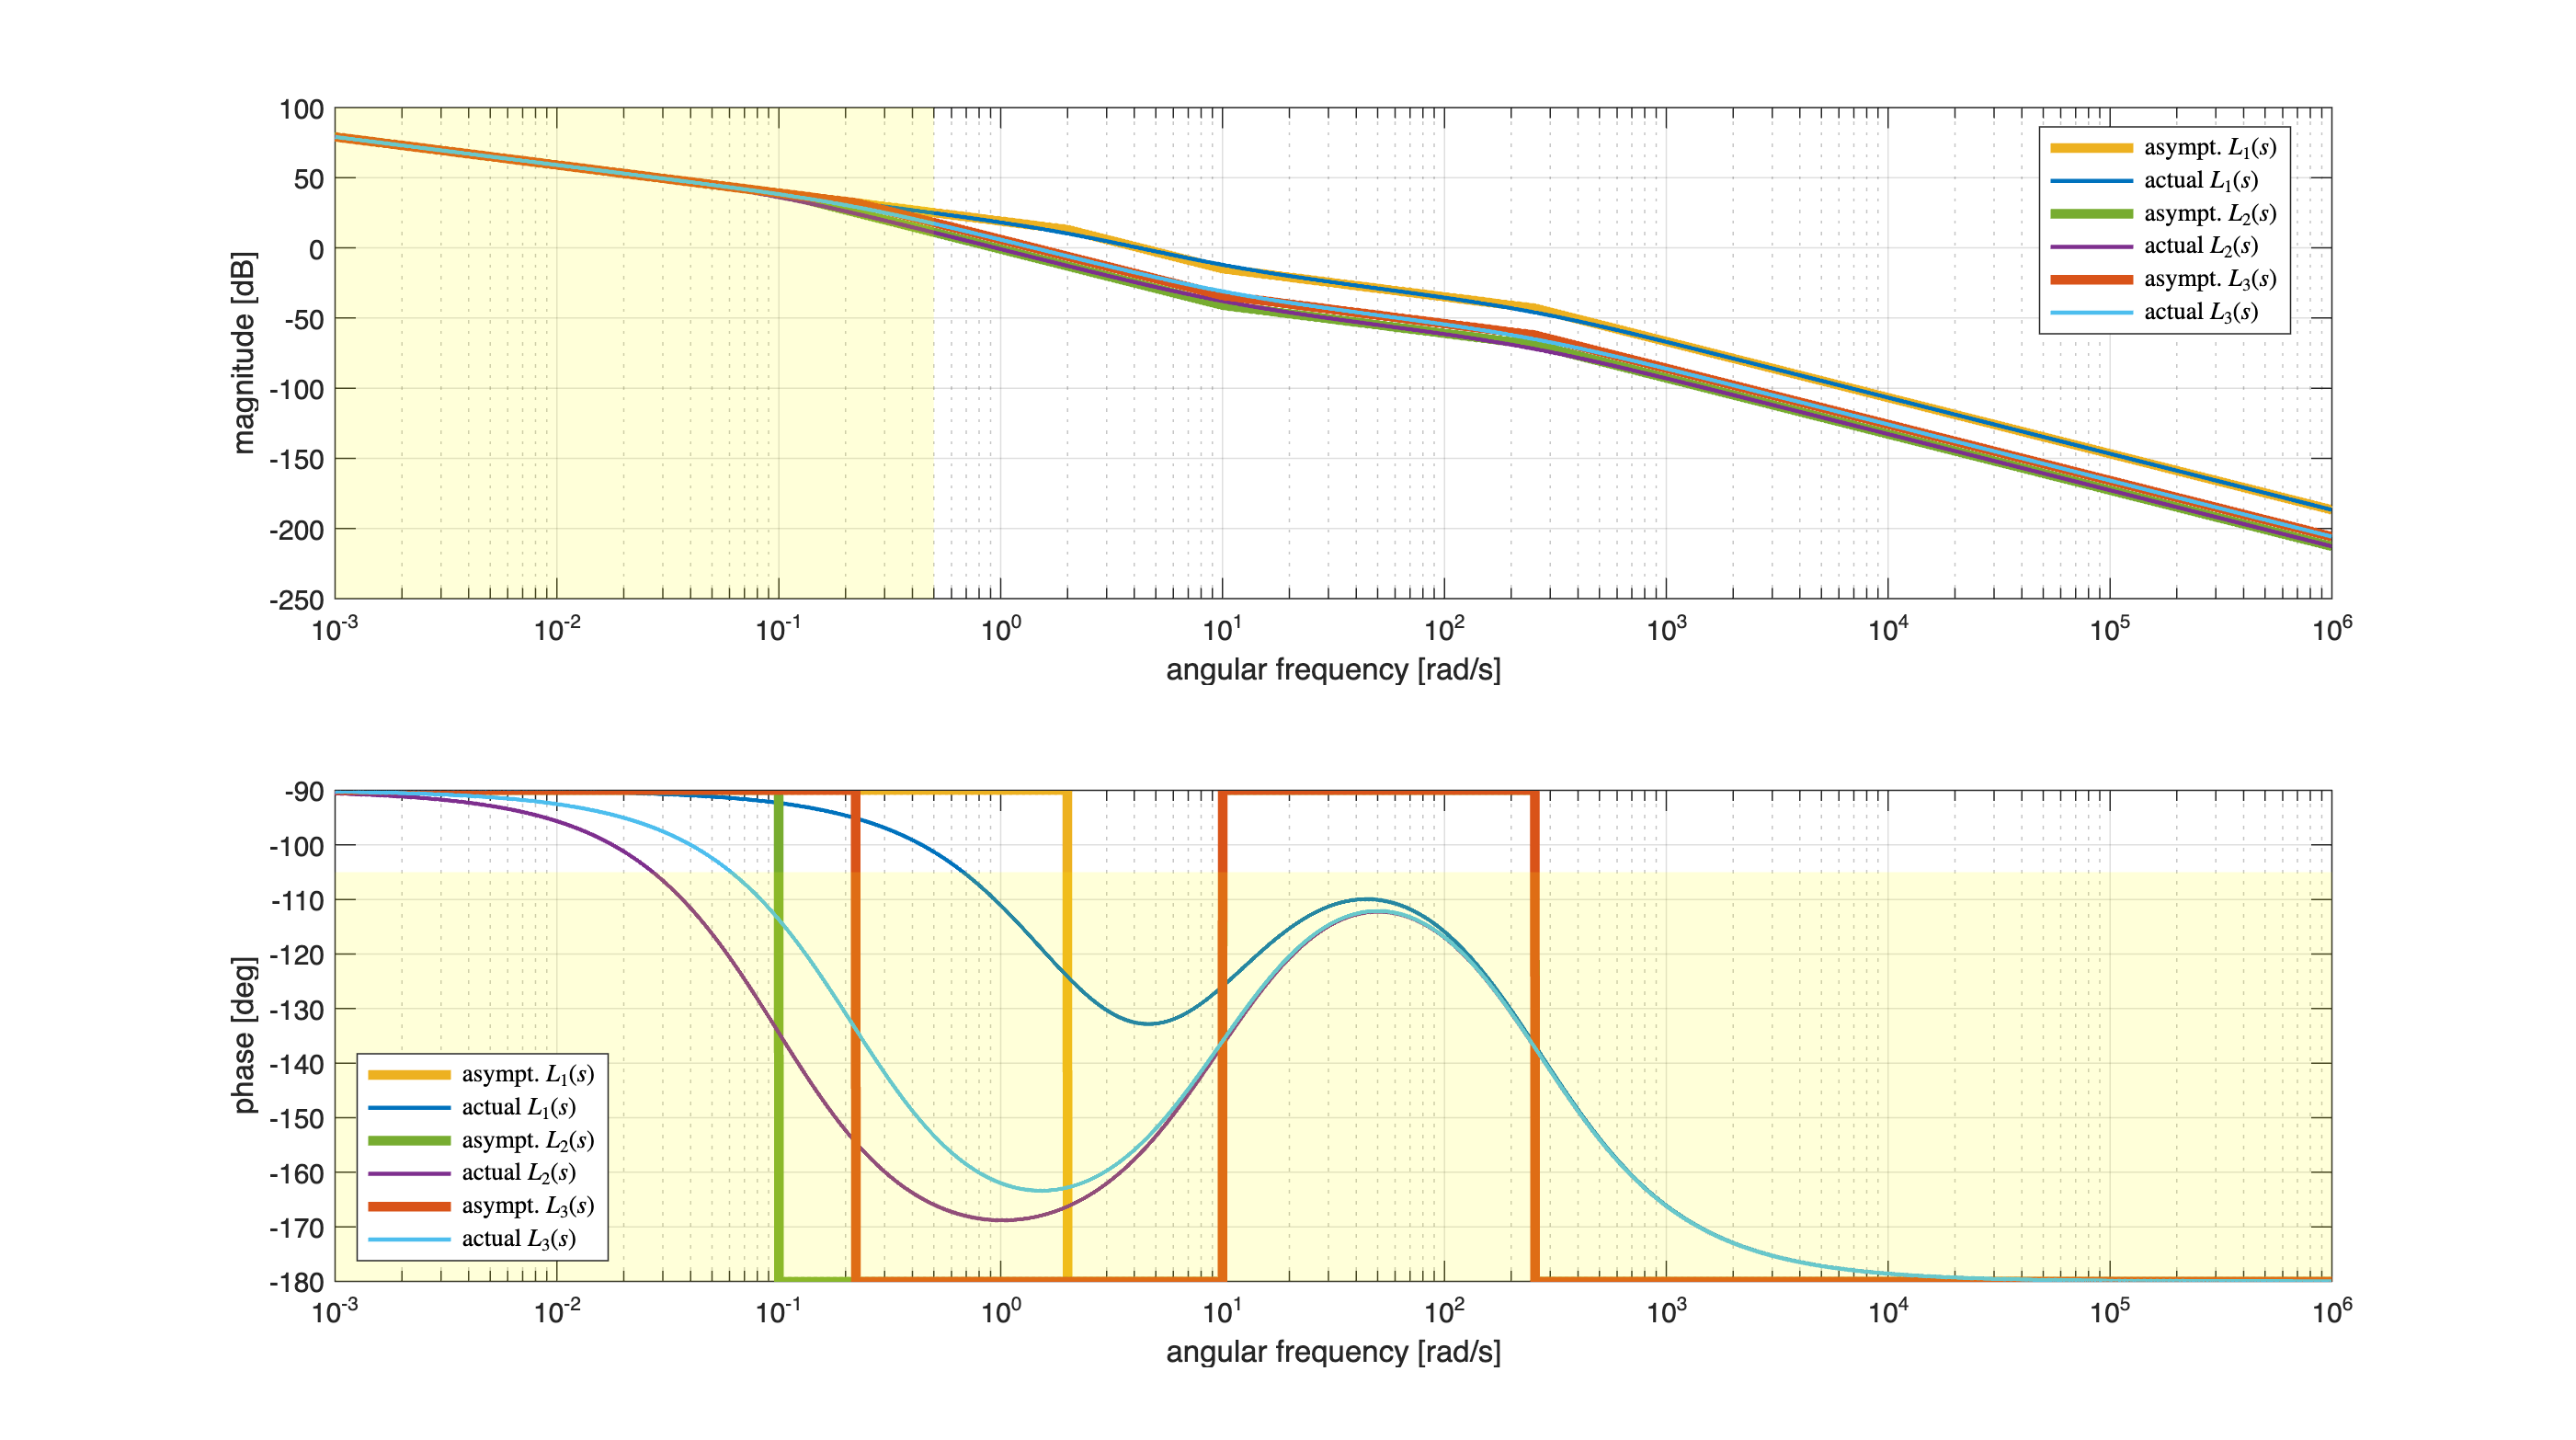

% the Bode diagrams

Bcolors = [0 0.4470 0.7410; ...
           0.9290 0.6940 0.1250; ...
           0.4940 0.1840 0.5560; ...
           0.4660 0.6740 0.1880; ...
           0.3010 0.7450 0.9330; ...
           0.8500 0.3250 0.0980; ...
           0.6350 0.0780 0.1840]; % some different colors 
                                 

hf = figure('Units','normalized','Position',[0.1, 0.1, 0.95, 0.85]);
drawBodediagrams(Ls1, [], Bcolors(2,:) , 3.5, [], Bcolors(1,:) ,1.5, [], hf);
drawBodediagrams(Ls2, [], Bcolors(4,:) , 3.5, [], Bcolors(3,:) ,1.5, [], hf);
[ha1, ha2] = drawBodediagrams(Ls3, [], Bcolors(6,:) , 3.5, [], Bcolors(5,:) ,1.5, [], hf);

phaseM = +75; % the desired minimum phase margin, according to (Q1.2)&(Q1.3)
feas_Ls_Phase = -180+phaseM; % the minimum value of the arg L(j omega) 
                             % to guarantee the feasibility of the design

YLIMS = ylim(ha2);
OMLIMs = xlim(ha2);
% the (Q1.2) constraint
minOmega1 = OMLIMs(1);
maxOmega1 = OMLIMs(2);
PhLIM = feas_Ls_Phase;

Vert1 = [minOmega1 ,  YLIMS(1); minOmega1 ,PhLIM; ...
         maxOmega1 , PhLIM; maxOmega1 , YLIMS(1)];
Faces1 = [1  2  3  4];
hold on;
patch(ha2, 'Faces',Faces1,'Vertices',Vert1,...
        'FaceColor','yellow','FaceAlpha',.15, ...
        'EdgeColor', 'none'); % the pale yellow region is the forbidden one

omC1 = 0.5; % constraint (Q1.3)&(Q1.2)
YLIMS = ylim(ha1);
OMLIMs = xlim(ha1);
minOmega1 = OMLIMs(1);
maxOmega1 = OMLIMs(2);
Vert2 = [minOmega1 ,  YLIMS(1); omC1 ,YLIMS(1); ...
         omC1 , YLIMS(2); minOmega1 , YLIMS(2)];
Faces2 = [1  2  3  4];
hold on;
patch(ha1, 'Faces',Faces2,'Vertices',Vert2,...
        'FaceColor','yellow','FaceAlpha',.15, ...
        'EdgeColor', 'none'); % the pale yellow region is the forbidden one

legend(ha1, 'asympt. $L_1(s)$', 'actual $L_1(s)$', ...
              'asympt. $L_2(s)$', 'actual $L_2(s)$', ...
              'asympt. $L_3(s)$', 'actual $L_3(s)$', ...
              'Interpreter', 'latex', 'Location', 'best')
legend(ha2, 'asympt. $L_1(s)$', 'actual $L_1(s)$', ...
              'asympt. $L_2(s)$', 'actual $L_2(s)$', ...
              'asympt. $L_3(s)$', 'actual $L_3(s)$', ...
              'Interpreter', 'latex', 'Location', 'southwest')

Without any modification to the controller $C(s)$ [i.e., without adding at least one zero in the second contribution to the controller $C_2(s)$ ], there is no way to fulfil the requirements (Q1.2) and (Q1.3).

What about the second scenario in Eq. $(*)$? Consider the minimum allowable value for the phase margin:


$$\varphi_m = 40^{\circ} \quad \Longrightarrow \quad \omega_c \ge \frac{46}{40} = 1.15\; \text{rad/sec}$$


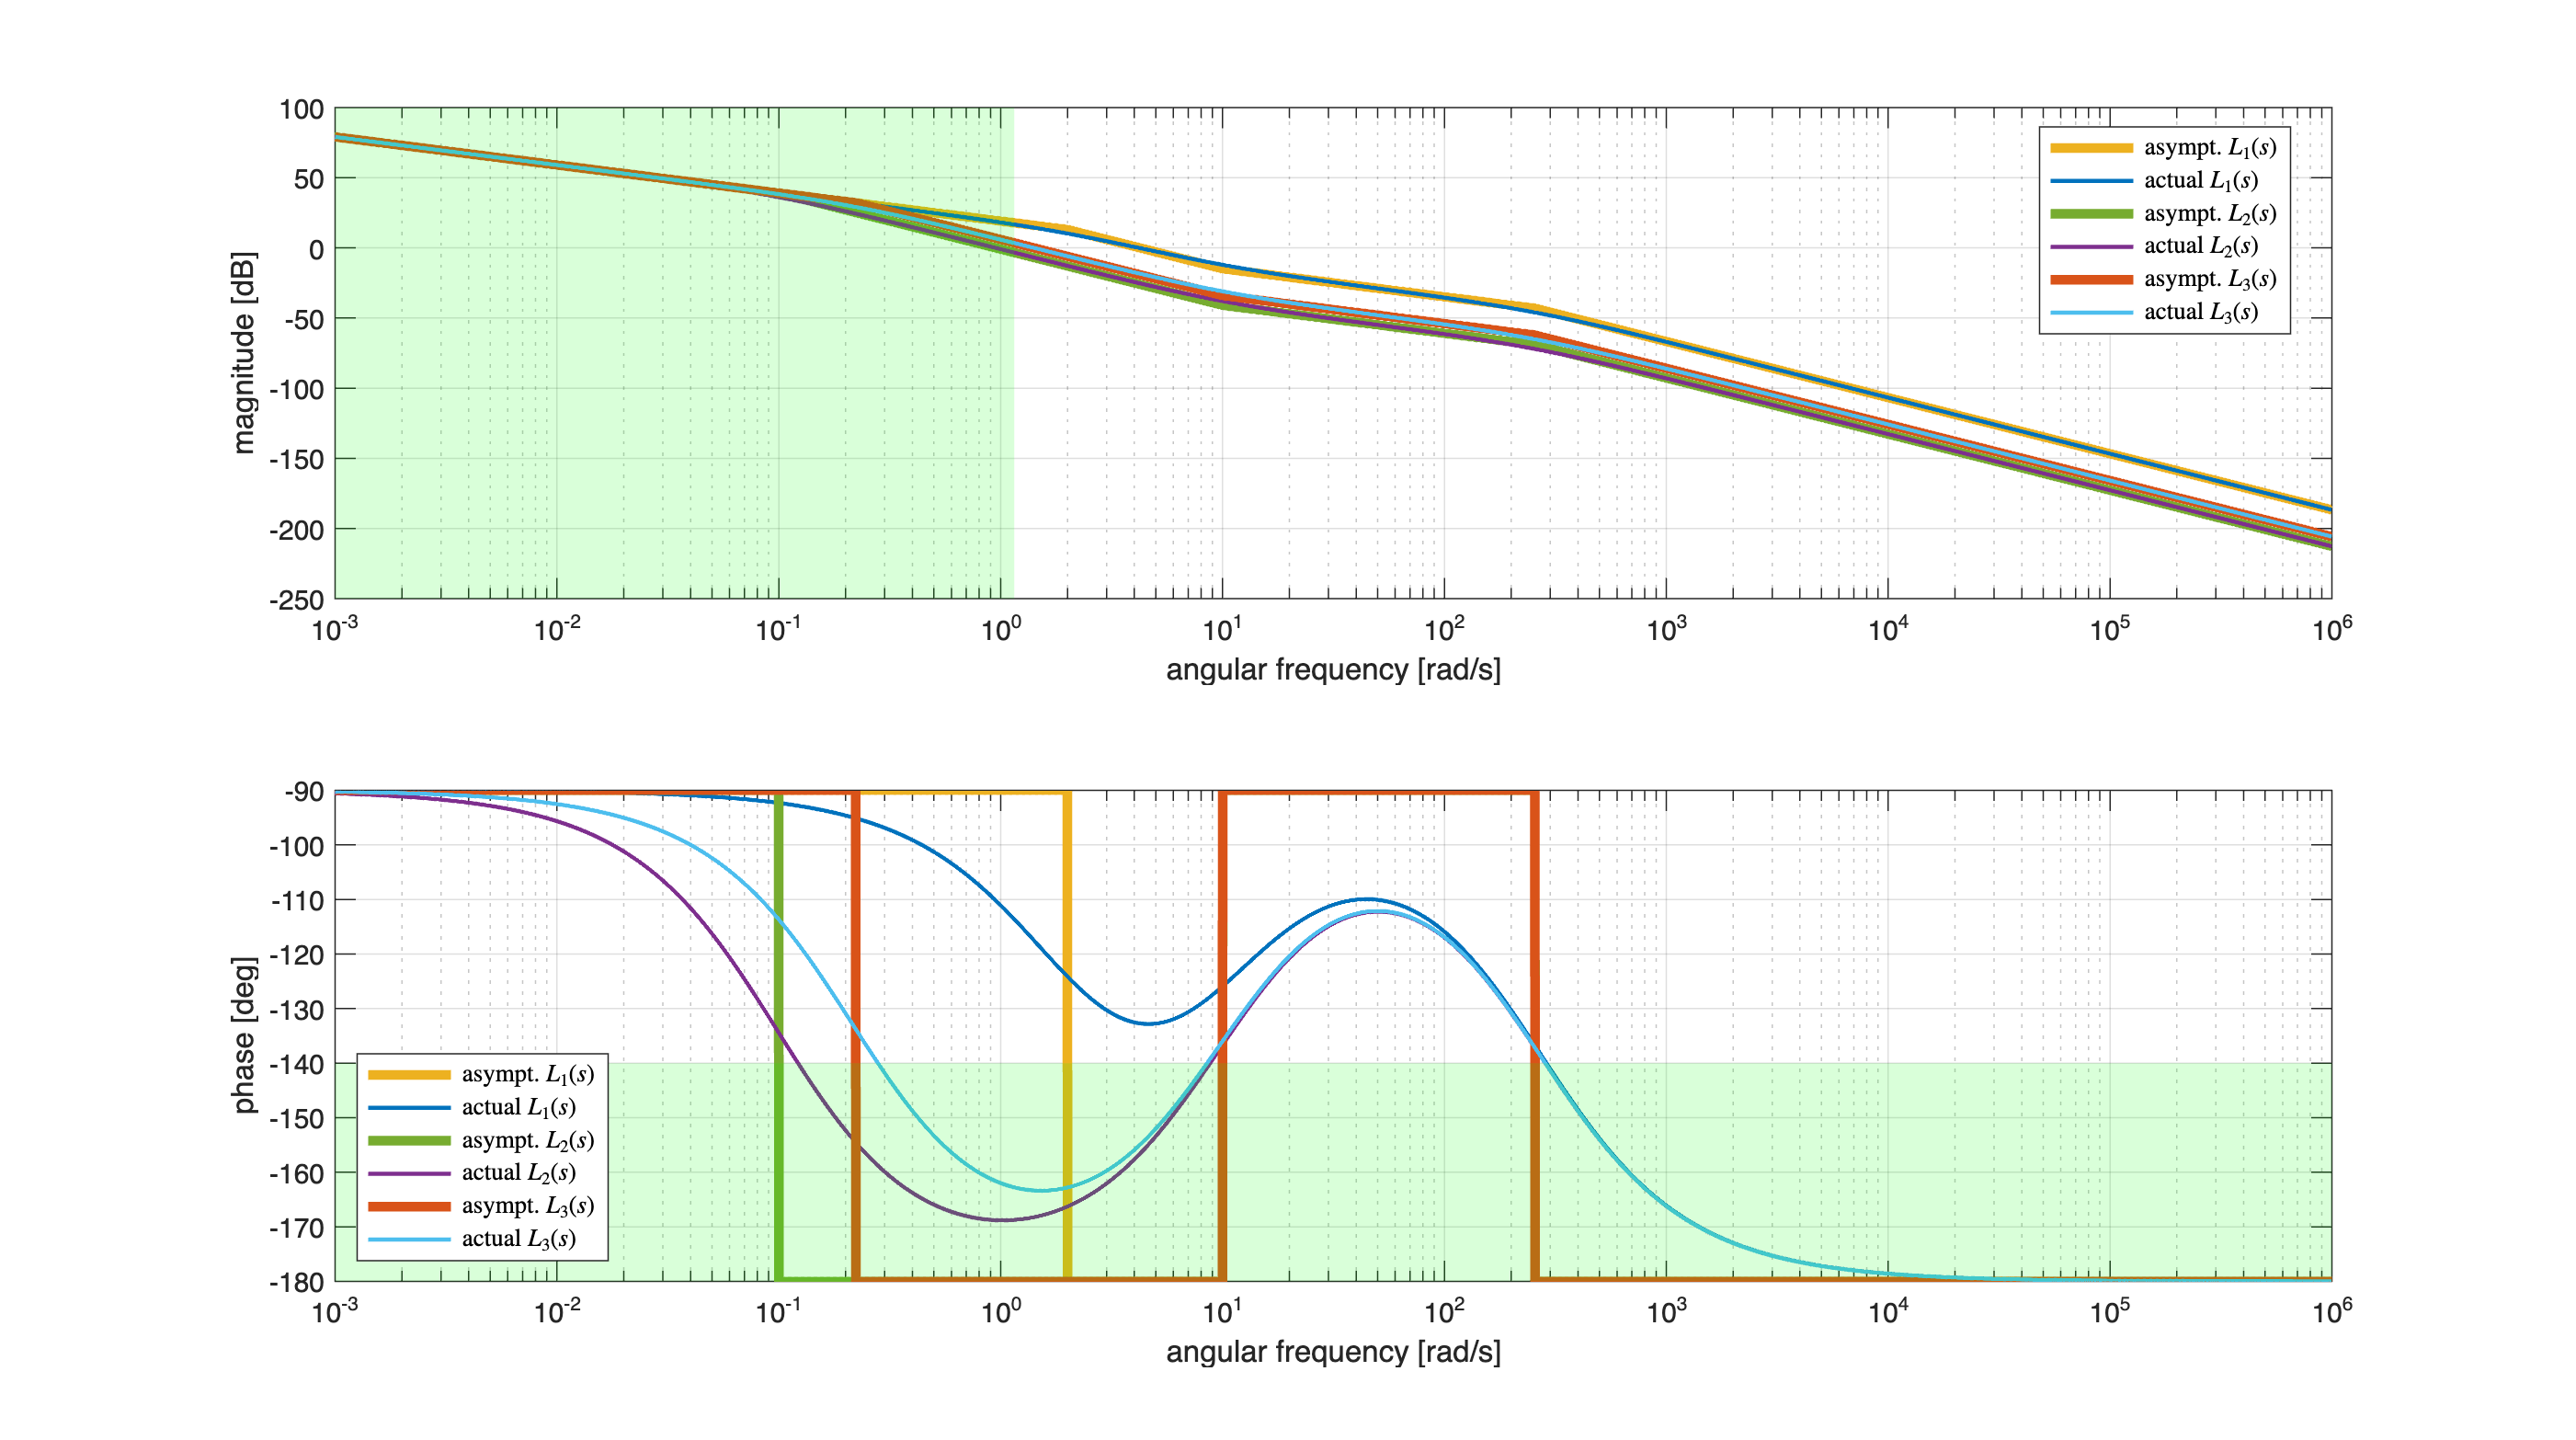

hf = figure('Units','normalized','Position',[0.1, 0.1, 0.95, 0.85]);
drawBodediagrams(Ls1, [], Bcolors(2,:) , 3.5, [], Bcolors(1,:) ,1.5, [], hf);
drawBodediagrams(Ls2, [], Bcolors(4,:) , 3.5, [], Bcolors(3,:) ,1.5, [], hf);
[ha1, ha2] = drawBodediagrams(Ls3, [], Bcolors(6,:) , 3.5, [], Bcolors(5,:) ,1.5, [], hf);

phaseM = +40; % the desired minimum phase margin, according to (Q1.2)&(Q1.3)
feas_Ls_Phase = -180+phaseM; % the minimum value of the arg L(j omega) 
                             % to guarantee the feasibility of the design

YLIMS = ylim(ha2);
OMLIMs = xlim(ha2);
% the (Q1.2) constraint
minOmega1 = OMLIMs(1);
maxOmega1 = OMLIMs(2);
PhLIM = feas_Ls_Phase;

Vert1 = [minOmega1 ,  YLIMS(1); minOmega1 ,PhLIM; ...
         maxOmega1 , PhLIM; maxOmega1 , YLIMS(1)];
Faces1 = [1  2  3  4];
hold on;
patch(ha2, 'Faces',Faces1,'Vertices',Vert1,...
        'FaceColor','green','FaceAlpha',.15, ...
        'EdgeColor', 'none'); % the pale yellow region is the forbidden one

omC1 = 1.15; % constraint (Q1.3)&(Q1.2)
YLIMS = ylim(ha1);
OMLIMs = xlim(ha1);
minOmega1 = OMLIMs(1);
maxOmega1 = OMLIMs(2);
Vert2 = [minOmega1 ,  YLIMS(1); omC1 ,YLIMS(1); ...
         omC1 , YLIMS(2); minOmega1 , YLIMS(2)];
Faces2 = [1  2  3  4];
hold on;
patch(ha1, 'Faces',Faces2,'Vertices',Vert2,...
        'FaceColor','green','FaceAlpha',.15, ...
        'EdgeColor', 'none'); % the pale yellow region is the forbidden one

legend(ha1, 'asympt. $L_1(s)$', 'actual $L_1(s)$', ...
              'asympt. $L_2(s)$', 'actual $L_2(s)$', ...
              'asympt. $L_3(s)$', 'actual $L_3(s)$', ...
              'Interpreter', 'latex', 'Location', 'best')
legend(ha2, 'asympt. $L_1(s)$', 'actual $L_1(s)$', ...
              'asympt. $L_2(s)$', 'actual $L_2(s)$', ...
              'asympt. $L_3(s)$', 'actual $L_3(s)$', ...
              'Interpreter', 'latex', 'Location', 'southwest')

This time, the design problem is feasible, with the simple controller $C_1(s) = \frac{\mu_C}{s}$ if we plan to obtain the crossover angular frequency in the interval $\omega_c \in \big[ 20\,,\; 100 \big] \; \text{rad/sec}$.

The worst-case scenario corresponds to the highest value for the time constant $\tau$, i.e., $\tau = 10$.

### Tuning the Controller

According to the previously performed analysis, any angular frequency $\omega \in \big[20\,,\;100\big] \; \text{rad/sec}$ allows to fulfil all the requirements.

Let's tune the gain constant $\mu_C$ with the aim to obtain $\bar \omega = 20$ rad/sec as crossover frequency in the worst-case scenario


$$\left\{\begin{array}{rcl}
C_1(s) &=& \frac{\mu_C}{s} \\
G_2(s) &=& 9\,\frac{\left(1+\frac{s}{10} \right)}{\left(1+\tau\,s \right)\,\left(1+\frac{s}{256} \right)}\;,\qquad \tau = 10\;\text{sec}
\end{array} \right. \quad \Longrightarrow \quad
 L_2(s) = 9\,\mu_C\, \frac{\left(1+\frac{s}{10} \right)}{s\,\left(1+10\,s \right)\,\left(1+\frac{s}{256} \right)}$$


Thus


$$\omega_c = 20 \quad \Longrightarrow \quad  \left|L_2(j20)\right| = 1 = 9\,\mu_C\, \left|  \frac{\left(1+\frac{j\,20}{10} \right)}{j20\,\left(1+10\cdot j20 \right)\,\left(1+\frac{j20}{256} \right)} \right|
  \quad  \Longrightarrow \quad \mu_C = ?$$


barOMc1 = 1j*10;
mag_L2s_barOMc1 = abs(freqresp(Ls2, barOMc1));
muC_VAL = 1/mag_L2s_barOMc1

muC_VAL = 78.6313

Verify the performance of the controller $C_1(s)$ in every scenario

C1s = muC_VAL/s; 

Ls1 = C1s*Gs1;
Ls2 = C1s*Gs2;
Ls3 = C1s*Gs3;

[gm, pm, o_gm, o_pm] = margin(Ls1)

gm = Inf

pm = 59.9932

o_gm = Inf

o_pm = 127.1391

Q1_2Q1_3_FLAG = (pm*o_pm >= 46) 

Q1_2Q1_3_FLAG = logical
   1



[gm2, pm2, o_gm2, o_pm2] = margin(Ls2)

gm2 = Inf

pm2 = 43.3360

o_gm2 = Inf

o_pm2 = 10

Q1_2Q1_3_FLAGbis = (pm2*o_pm2 >= 46) 

Q1_2Q1_3_FLAGbis = logical
   1



[gm3, pm3, o_gm3, o_pm3] = margin(Ls3)

gm3 = Inf

pm3 = 57.5820

o_gm3 = Inf

o_pm3 = 17.9554

Q1_2Q1_3_FLAGter = (pm3*o_pm3 >= 46) 

Q1_2Q1_3_FLAGter = logical
   1


In conclusion, the controller $C_1(s)$ allows to fulfil every requirement.

### Fine Tuning the Controller using the controlSystemDesigner App

% let's create a multi-model structure
Gs = stack(1, Gs1, Gs2, Gs3);

controlSystemDesigner(Gs, C1s)

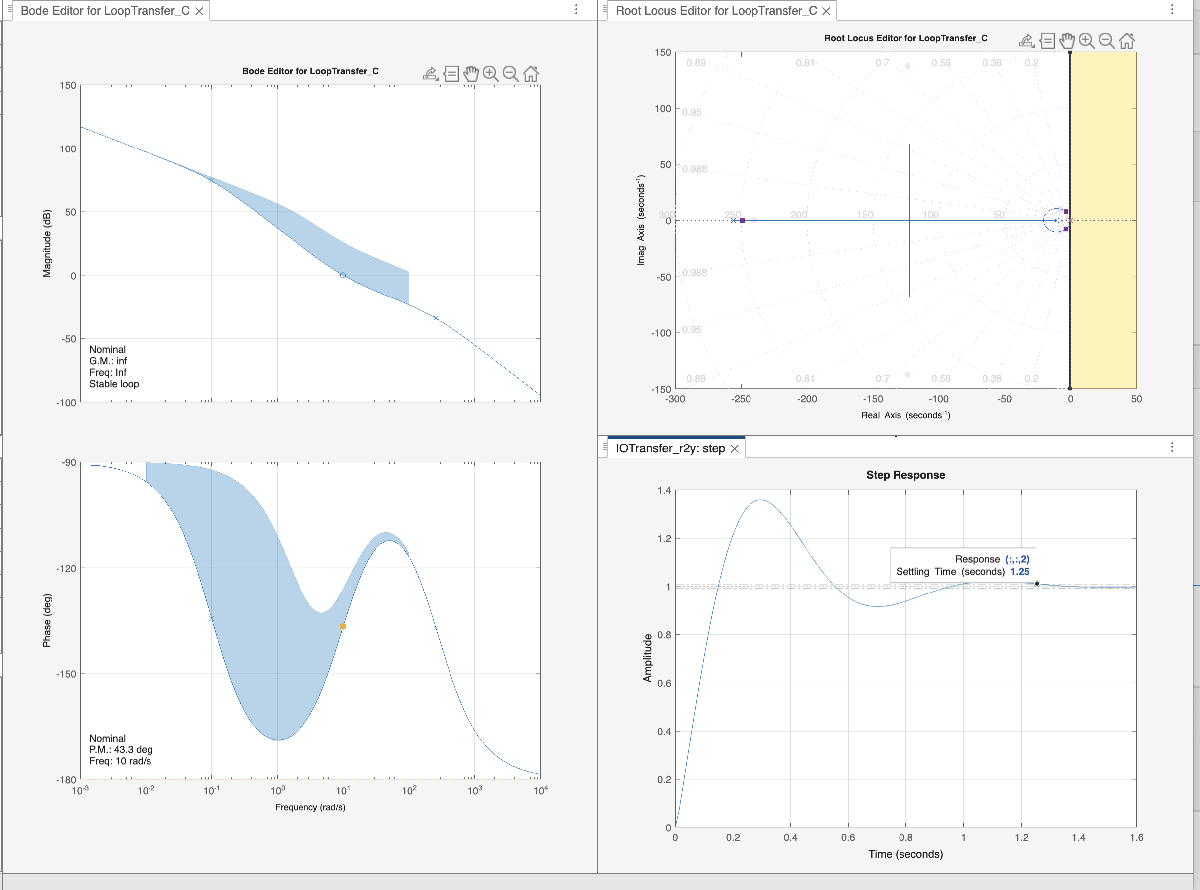

The corresponding controlSystremDesigner session file is `multimodel_solution_2025_06_06_FA_gr_B_ControlSystemDesignerSession.mat`